# OGLO notebook 1

hnxj@github

## 1: Population iFR plots

RRRR

ifrm = cell(12, 10);
ifrs = cell(12, 10);

for k = 1:10

    for conds = 1:12

        ifrm{conds, k} = zeros(areaCounts(k), 6000);
        ifrs{conds, k} = zeros(areaCounts(k), 6000);
        ncount = 0;

        for l = 1:size(z{k}{1}, 2)
    
            ytm = squeeze(mean(z{k}{conds}{l}, 1));
            yts = squeeze(std(z{k}{conds}{l}, 1)) / sqrt(100);
            ytm(isnan(ytm)) = mean(ytm, 'all', 'omitnan');
            ytm(isnan(ytm)) = 0;
            yts(isnan(yts)) = 0;
    
            N = min(size(ytm));
    
            ifrm{conds, k}(ncount+1:ncount+N, :) = ytm;
            try
                ifrs{conds, k}(ncount+1:ncount+N, :) = yts;
            catch
                ifrs{conds, k}(ncount+1:ncount+N, :) = 0;
            end
            ncount = ncount + N;
    
        end

    end

    fprintf(num2str(k) + "-");

end

1-2-3-4-5-6-7-8-9-10-

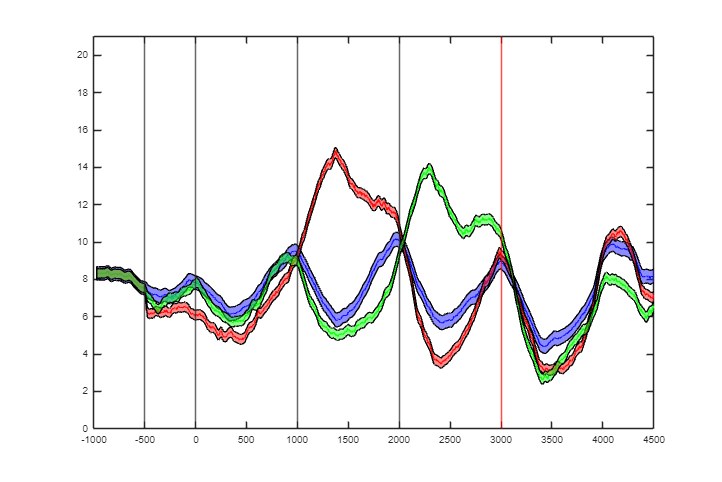

% figure("Position", [0 0 1500 1000]);

t = linspace(-970, 4850, 6000);

for ik = 9:9

    % subplot(5, 2, ik);

    figure("Position", [0 0 1500 1000]);
    ksize = 400;
    ksize2 = 25;

    if ik == 4 || ik == 3

        ksize = 400;

    end

    idxx = 44;
    ix1 = mean(ifrm{1, ik}(idxx, :), 1);
    ix2 = mean(ifrm{2, ik}(idxx, :), 1);
    ix3 = mean(ifrm{3, ik}(idxx, :), 1);
    ix4 = mean(ifrm{4, ik}(idxx, :), 1);

    ix1(1:100) = mean(ix1(1:200));
    ix2(1:100) = mean(ix1(1:200));
    ix3(1:100) = mean(ix1(1:200));

    ix1(1:500) = smooth(ix1(1:500), 10);
    ix2(1:500) = smooth(ix1(1:500), 10);
    ix3(1:500) = smooth(ix1(1:500), 10);

    ix1 = smooth(detrend(ix1'), ksize);
    ix2 = smooth(detrend(ix2'), ksize);
    ix3 = smooth(detrend(ix3'), ksize);
    % ix1 = ix1 - mean(ix2(1:5000)-ix1(1:5000));
    ix1(1:100) = mean(ix1(1:200));
    ix2(1:100) = mean(ix2(1:200));
    ix3(1:100) = mean(ix3(1:200));

    ix1(1:500) = smooth(ix1(1:500), 10);
    ix2(1:500) = smooth(ix1(1:500), 10);
    ix3(1:500) = smooth(ix1(1:500), 10);

    is1 = smooth(mean(ifrs{1, ik}, 1), ksize*2) / 5;
    is2 = smooth(mean(ifrs{2, ik}, 1), ksize*2) / 5;
    is3 = smooth(mean(ifrs{3, ik}, 1), ksize*2) / 5;
    baselinem = - min((ix1 + ix2));

    sth1 = smooth(ix1, ksize2) + is1 + baselinem;
    stl1 = smooth(ix1, ksize2) - is1 + baselinem;
    sth2 = smooth(ix2, ksize2) + is2 + baselinem;
    stl2 = smooth(ix2, ksize2) - is2 + baselinem;
    sth3 = smooth(ix3, ksize2) + is3 + baselinem;
    stl3 = smooth(ix3, ksize2) - is3 + baselinem;
    
    plot(t, ix1 + baselinem, "b");hold("on");
    plot(t, ix2 + baselinem, "r");
    plot(t, ix3 + baselinem, "g");
    patch([t, t(end:-1:1)], [sth1;stl1(end:-1:1)], [0.1 0.1 1.0], "FaceAlpha", 0.5);
    patch([t, t(end:-1:1)], [sth2;stl2(end:-1:1)], [1.0 0.1 0.1], "FaceAlpha", 0.5);
    patch([t, t(end:-1:1)], [sth3;stl3(end:-1:1)], [0.1 1.0 0.1], "FaceAlpha", 0.5);

    xline(-500);
    xline(0);
    xline(1000);
    xline(2000);
    xline(3000, "r");
    xlim([-1000 4500]);
    ylim([0 max(sth1)*2]);
    % title(areaNames{ik} + ", N = " + num2str(areaCounts(ik)));

    fname = num2str(idxx) + "_rifr_" + areaNames{ik};
    % print(gcf,'-vector','-dsvg', fname +".svg");

end

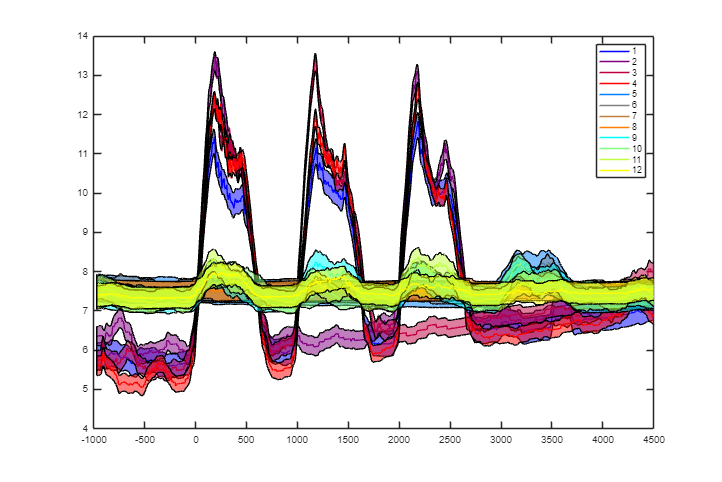

t = linspace(-970, 4850, 6000);
color_ = zeros(12, 3);
color_(1:4, 2) = 0.0;
color_(5:8, 2) = 0.5;
color_(9:12, 2) = 1.0;

color_([1, 5, 9], 1) = 0.0;
color_([2, 6, 10], 1) = 0.5;
color_([3, 7, 11], 1) = 0.75;
color_([4, 8, 12], 1) = 1.0;

color_([1, 5, 9], 3) = 1.0;
color_([2, 6, 10], 3) = 0.5;
color_([3, 7, 11], 3) = 0.25;
color_([4, 8, 12], 3) = 0.0;

for ik = 8:8

    % subplot(5, 2, ik);

    figure("Position", [0 0 1500 1000]);
    ksize = 200;
    ksize2 = 25;

    idxx = 44;

    for jk = 1:12
    
        ix1 = mean(ifrm{jk, ik}(idxx, :), 1);

        ix1(1:100) = mean(ix1(1:200));

        ix1(1:500) = smooth(ix1(1:500), 10);

        ix1 = smooth(detrend(ix1'), ksize);

        is1 = smooth(mean(ifrs{jk, ik}, 1), ksize*2) / 5;

        sth1 = smooth(ix1, ksize2) + is1 + baselinem;
        stl1 = smooth(ix1, ksize2) - is1 + baselinem;
    
        plot(t, ix1 + baselinem, "Color", [color_(jk, :)], "DisplayName", num2str(jk));hold("on");
        patch([t, t(end:-1:1)], [sth1;stl1(end:-1:1)], [color_(jk, :)], "FaceAlpha", 0.5, "HandleVisibility", "off");

        xlim([-1000 4500]);

    end
    legend;

    fname = string(areaNames{ik}) + num2str(idxx) + "_allfr";
    print(gcf,'-vector','-dsvg', fname +".svg");

end

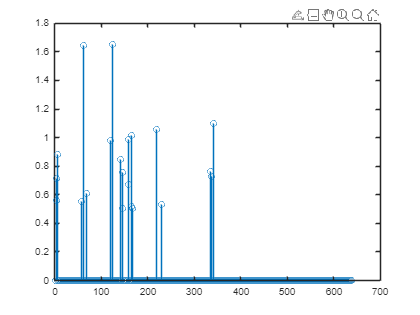

ik = 10;
ic1 = mean(ifrm{1, ik}(:, 4501:5000), 2);
ic2 = mean(ifrm{2, ik}(:, 4501:5000), 2);
ic3 = mean(ifrm{3, ik}(:, 4501:5000), 2);
figure;
icx = ((ic2+ic3)-(2*ic1))./(2*ic1);
% icx(icx>0.5) = 1;
icx(icx<0.5) = 0;
icx(ic1 < 1) = 0;
stem(icx);

## End